## Relatório Projeto 2 - Matemática Computacional

### 1

### a) e b)

format Long
t = [1 2 5 7 8 9 12]

t =      1     2     5     7     8     9    12


ft = [0.9 0.4 0.18 0.2 0.22 0.27 0.36]

ft =    0.900000000000000   0.400000000000000   0.180000000000000   0.200000000000000   0.220000000000000   0.270000000000000   0.360000000000000


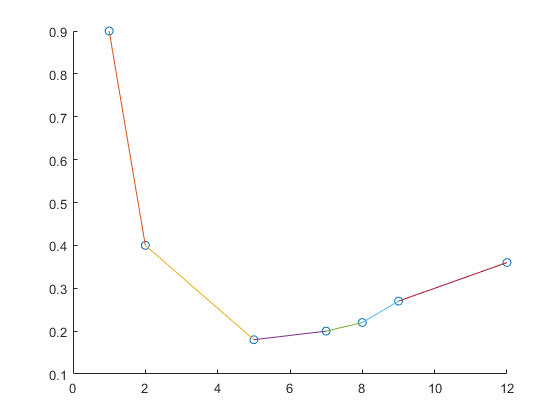

splinelinear(t,ft)

### c)

getvalue(t,ft,3)

ans =    0.340000000000000


A fórmula de erro para

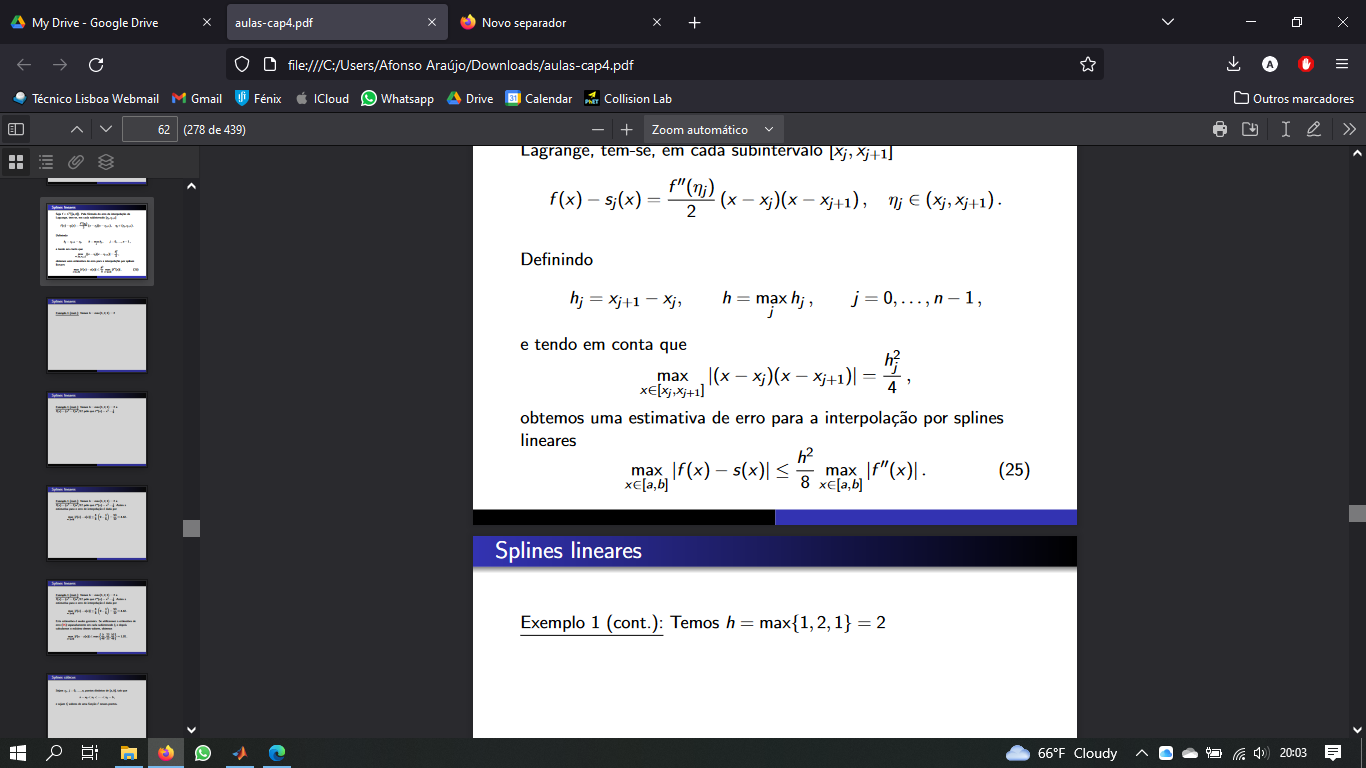

 0<f''(x)<1

calculamos os h para saber qual o máximo

%Descobrir o h máximo
n = numel(t)

n =      7


hmax = 0;
for i = 1:1:n-1
    if t(i+1)-t(i) > hmax
        hmax = t(i+1)-t(i);
    end
end

Considerando o pior dos casos para a 2 derivada de f no intervalo [1,12] podemos majorar o erro da seguinte forma:

M = ((hmax.^2)./8).*(1)

M =    1.125000000000000


Ainda assim este erro é muito grosseiro. Ao utilizar a fórmula de erro para cada subintervalo temos no ponto t=3:

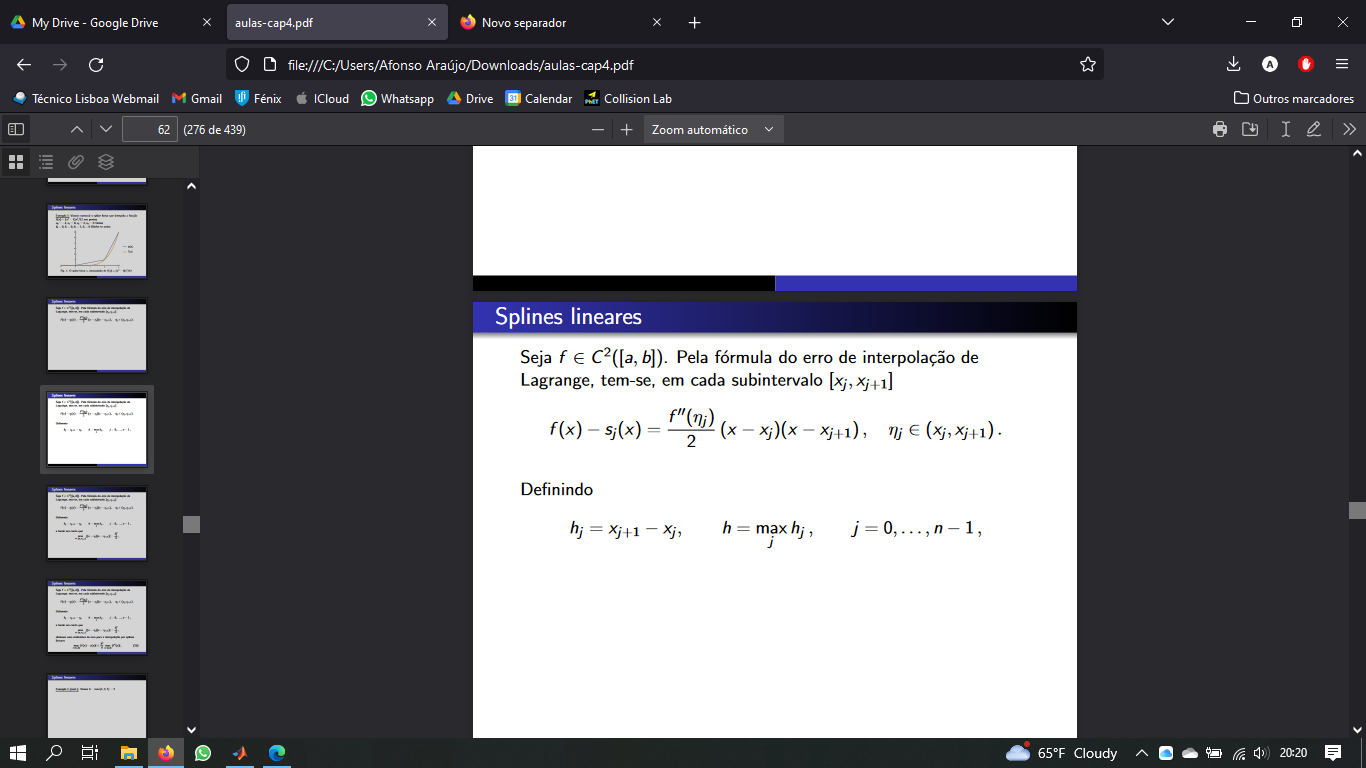

N = (1./2).*(3-2).*(3-5)

N =     -1


**Esta fórmula serve para aqui???**

### d)

Definem-se as funções de base

phi0 = @(t) exp(-3.*t)

phi0 = function_handle with value:
    @(t)exp(-3.*t)


phi1 = @(t) exp(0.1.*t)

phi1 = function_handle with value:
    @(t)exp(0.1.*t)


phi2 = @(t) exp(-t)

phi2 = function_handle with value:
    @(t)exp(-t)



coef = minq3(t,ft,phi0,phi1,phi2)

coef =    1.078218315985077
   0.104905974210165
   1.985444480853854



f = @(t) coef(1).*phi0(t) + coef(2).*phi1(t) + coef(3).*phi2(t)

f = function_handle with value:
    @(t)coef(1).*phi0(t)+coef(2).*phi1(t)+coef(3).*phi2(t)


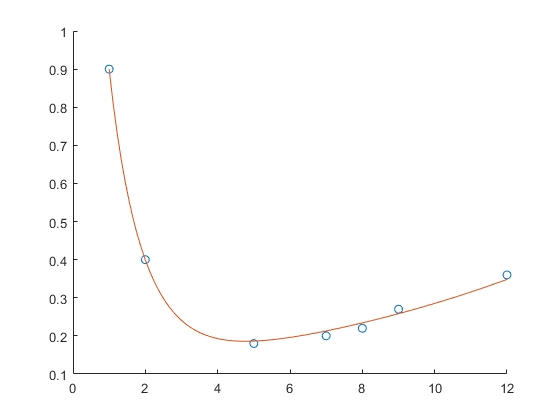


scatter(t,ft)
hold on
x = linspace(1,12,100);
plot(x,f(x))
hold off

### 2.

### a)

volexact = 3.198423723387142

volexact =    3.198423723387142


g = @(x) pi.*(exp(-cos(x))).^2;
a = 1;
b = 2;
n = 100; %número de intervalos
[vol,~] = Trapcomp(g,a,b,n);
vol

vol =    3.198518207485261



h = [];
v = [];
erros = [];
ni = 100;
for i = 1:1:ni
    [v(i),h(i)] = Trapcomp(g,a,b,i);
    e(i) = abs(v(i)-volexact);
end
R = [h' e']

R =    1.000000000000000   0.945297976182399
   0.500000000000000   0.237009910130175
   0.333333333333333   0.105163813275201
   0.250000000000000   0.059112373730422
   0.200000000000000   0.037818563743242
   0.166666666666667   0.026257704906607
   0.142857142857143   0.019289040894399
   0.125000000000000   0.014767000915370
   0.111111111111111   0.011667115483456
   0.100000000000000   0.009449992101766


Rlin = [log(h)' log(e)']

Rlin =                    0  -0.056255082479358
  -0.693147180559945  -1.439653323825970
  -1.098612288668110  -2.252236018127066
  -1.386294361119891  -2.828315007103719
  -1.609437912434100  -3.274955192590294
  -1.791759469228055  -3.639795812761448
  -1.945910149055313  -3.948218173653158
  -2.079441541679836  -4.215360255502934
  -2.197224577336220  -4.450981036890251
  -2.302585092994045  -4.661741373268828



logh = log(h);
loge = log(e);
scatter(logh, loge)
hold on

phi4 = @(t) (x == 0) .* 1 + (x ~= 0) .* 1;
phi5 = @(t) t;

coef = minq2(log(h),log(e),phi4,phi5)

coef =   -0.055661920760211
   2.000268533575437


fminq = @(x) coef(1) + coef(2).*x

fminq = function_handle with value:
    @(x)coef(1)+coef(2).*x


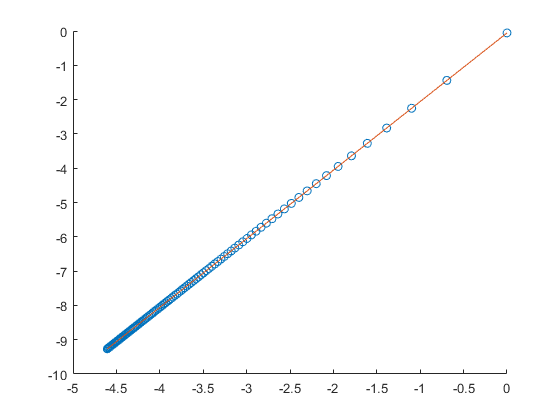


x = linspace(logh(1),logh(end),100);
plot(x, fminq(x))
hold off

p = 2 justificar que é o coeficiente 

### b)

### Definição de Funções

%Calculo do integral pela regra dos Trapézios Composta
function [res,h] = Trapcomp(f,a,b,n)
int = linspace(a,b,n+1);
h = abs(a-b)/n;
res = 0;
for i = 1:1:numel(int)-1
    res = res + (f(int(i))+f(int(i+1))).*h/2;
end
end

%Função dos mínimos quadrados para 2 funções de base
function v = minq2(t,ft,phi0,phi1)
A = [dot(phi0(t),phi0(t)) dot(phi0(t),phi1(t));
     dot(phi1(t),phi0(t)) dot(phi1(t),phi1(t))];
b = [dot(ft,phi0(t));
     dot(ft,phi1(t))];
v = A\b;
end

%Função dos mínimos quadrados para 3 funções de base
function v = minq3(t,ft,phi0,phi1,phi2)
A = [dot(phi0(t),phi0(t)) dot(phi0(t),phi1(t)) dot(phi0(t),phi2(t));
     dot(phi1(t),phi0(t)) dot(phi1(t),phi1(t)) dot(phi1(t),phi2(t));
     dot(phi2(t),phi0(t)) dot(phi2(t),phi1(t)) dot(phi2(t),phi2(t))];
b = [dot(ft,phi0(t));
     dot(ft,phi1(t));
     dot(ft,phi2(t))];
v = A\b;
end

%Função produto interno
function [c] = dot(a,b)
n = numel(a);
c = 0;
for i = 1:1:n
    c = c + a(i).*b(i);
end
end

%Função que encontra uma aproximação para um dado t recorrendo ao spline linear
function [b] = getvalue(t,ft,a)
n = numel(t);      
min = t(1);     %encontrar entre que pontos está o 'a' pedido
for i = 1:1:n
    if t(i) > a
        min = t(i-1);
        max = t(i);
        break
    end
end
b =  ft(min)+(ft(max)-ft(min)).*(a-min)./(max-min);
end

%Função que desenha o spline linear
function [] = splinelinear(t,ft)
scatter(t,ft)
hold on
x = linspace(1,12,100);
n = numel(t);
for i = 1:1:n-1
    s = @(x) ft(i)+(ft(i+1)-ft(i)).*(x-t(i))./(t(i+1)-t(i));
    fplot(s,[t(i),t(i+1)])
end
hold off
end